In order to explore the possibility of amino acid optimization having effects on fitness (and justify the use of whole-genome models) we alter the AA composition of the enzyme and observe the effects on the cells' final yield.

Data is generated in the script optima/aminos/s4_generate_variable_AA.m

[nrows,ncols] = size(tab);
%add a few data columns
for i = 1:nrows
    tab.biomass_final(i) = tab.biomass{i}.biomass(end);
    tab.cellulose_final(i) = tab.cellulose{i}(end);
    tab.glucose_final(i) = tab.glucose{i}(end);
    tab.enzyme_final(i) = tab.enzyme{i}(end);
end


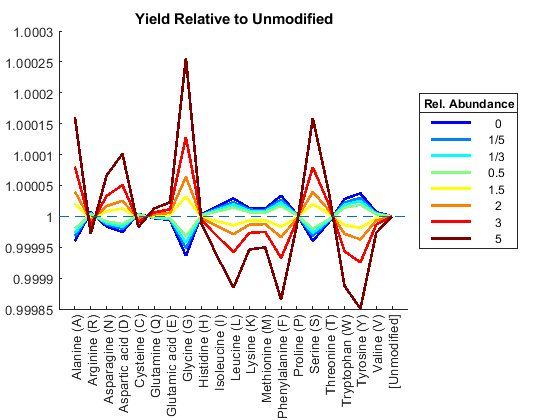

foldchanges = unique(tab.foldchange);
colors = jet(length(foldchanges));
figure();
hold on;
for i = 1:length(foldchanges)
    d = tab(tab.foldchange == foldchanges(i),:);
    plot(d.biomass_final/d.biomass_final(21),'lineWidth',2,'color',colors(i,:));
end
xlim([0 22]);
hold off;
%ylim([.9999 1]);
ref = refline(0,1);
set(ref,'LineStyle','--');
legendstrs = num2str(foldchanges);
legendstrs(2,:) = [repelem(' ',length(legendstrs(2,:))-3) '1/5'];
legendstrs(3,:) = [repelem(' ',length(legendstrs(3,:))-3) '1/3'];
leg = legend(legendstrs,'location','eastoutside');
title(leg,'Rel. Abundance');
title('Yield Relative to Unmodified');
aanames = {'Alanine (A)' 'Arginine (R)' 'Asparagine (N)' 'Aspartic acid (D)' 'Cysteine (C)'...
'Glutamine (Q)' 'Glutamic acid (E)' 'Glycine (G)' 'Histidine (H)' 'Isoleucine (I)'...
'Leucine (L)' 'Lysine (K)' 'Methionine (M)' 'Phenylalanine (F)' 'Proline (P)'...
'Serine (S)' 'Threonine (T)' 'Tryptophan (W)' 'Tyrosine (Y)' 'Valine (V)' '[Unmodified]'};
c = categorical(aanames);
set(gca,'XTick',1:21);
set(gca,'XTickLabel',aanames);
set(gca,'XTickLabelRotation',90);

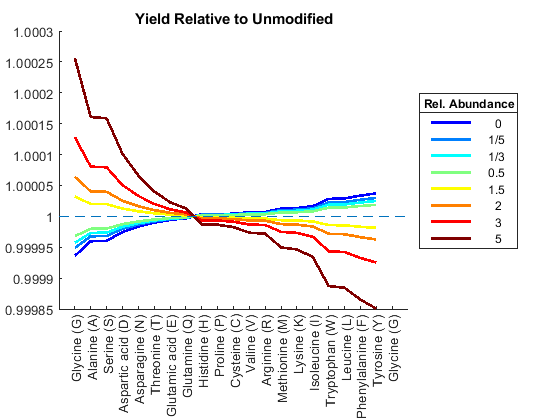

figure();
hold on;
d2 = d(~strcmp(d.AA,'none'),:);
[sorted,order] = sort(d2.biomass_final,'descend');
for i = 1:length(foldchanges)
    d = tab(tab.foldchange == foldchanges(i),:);
    d2 = d(~strcmp(d.AA,'none'),:);
    d2 = d2(order,:);
    plot(d2.biomass_final/d.biomass_final(21),'lineWidth',2,'color',colors(i,:));
end
xlim([0 22]);
hold off;
%ylim([.9999 1]);
ref = refline(0,1);
set(ref,'LineStyle','--');
legendstrs = num2str(foldchanges);
legendstrs(2,:) = [repelem(' ',length(legendstrs(2,:))-3) '1/5'];
legendstrs(3,:) = [repelem(' ',length(legendstrs(3,:))-3) '1/3'];
leg = legend(legendstrs,'location','eastoutside');
title(leg,'Rel. Abundance');
title('Yield Relative to Unmodified');
c = categorical(aanames);
set(gca,'XTick',1:21);
set(gca,'XTickLabel',aanames(order));
set(gca,'XTickLabelRotation',90);

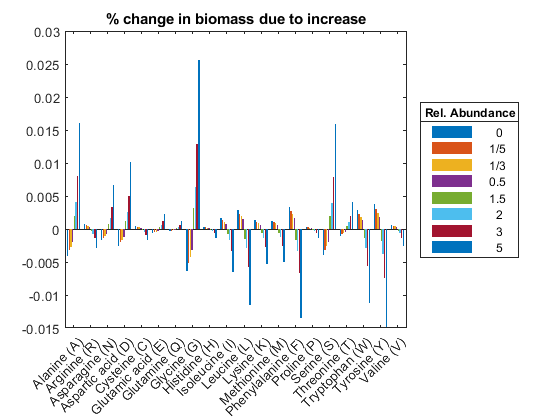

figure();
dv = zeros(length(foldchanges),20);
for i = 1:length(foldchanges)
    d = tab(tab.foldchange == foldchanges(i),:);
    dv(i,:) = 100 * ((d.biomass_final(1:20)/d.biomass_final(21)) - 1);
end
bar(categorical(aanames(1:20)),dv');
leg = legend(legendstrs,'location','eastoutside');
title(leg,'Rel. Abundance');
title('% change in biomass due to increase');

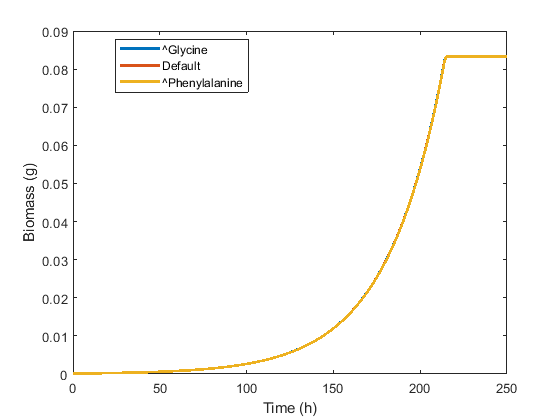

%xlim([0,21]);
d = tab(tab.foldchange == max(foldchanges),:);
plot(tab.t{8},d.biomass{8}.biomass,d.t{21},d.biomass{21}.biomass,d.t{14},d.biomass{14}.biomass,'lineWidth',2)
legend({'\^Glycine' 'Default' '\^Phenylalanine'},'location','best')
xlabel('Time (h)')
ylabel('Biomass (g)')

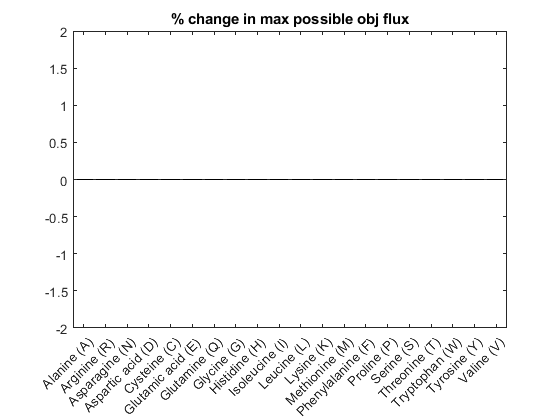

%Maximum possible objective flux
% bar(c,tab.max_obj_flux);
% title('Max Possible Objective Flux');
% 
% bar(categorical(aanames(1:20)),tab.max_obj_flux(1:20)/tab.max_obj_flux(21))
% title('Max Flux relative to Unmodified Max')
% ylim([.95 1])
dv = zeros(length(foldchanges),20);
for i = 1:length(foldchanges)
    d = tab(tab.foldchange == foldchanges(i),:);
    dv(i,:) = 100*((tab.max_obj_flux(1:20)/tab.max_obj_flux(21))-1);
end
bar(categorical(aanames(1:20)),100*((tab.max_obj_flux(1:20)/tab.max_obj_flux(21))-1))
title('% change in max possible obj flux')
ylim([-2 2])

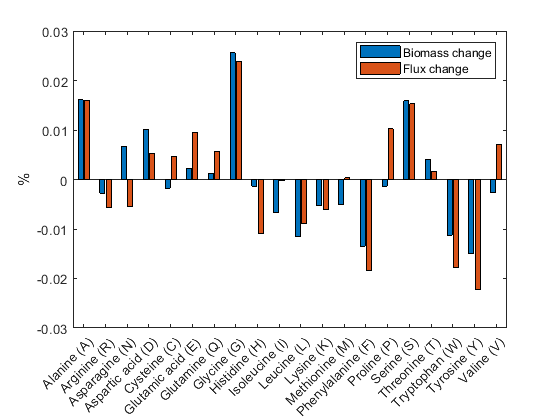


d = tab(tab.foldchange == max(foldchanges),:);
fluxbars = 100*((d.max_obj_flux(1:20)/d.max_obj_flux(21))-1);
biobars = 100 * ((d.biomass_final(1:20)/d.biomass_final(21)) - 1);
bar(categorical(aanames(1:20)),horzcat(biobars,fluxbars))
legend({'Biomass change' 'Flux change'});
ylabel('%')

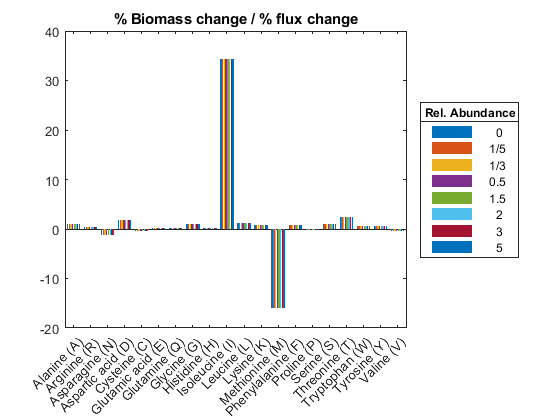


dv = zeros(length(foldchanges),20);
for i = 1:length(foldchanges)
    d = tab(tab.foldchange == foldchanges(i),:);
    fluxbars = 100*((d.max_obj_flux(1:20)/d.max_obj_flux(21))-1);
    biobars = 100 * ((d.biomass_final(1:20)/d.biomass_final(21)) - 1);
    dv(i,:) = biobars./fluxbars;
end
bar(categorical(aanames(1:20)),dv');
title('% Biomass change / % flux change');
leg = legend(legendstrs,'location','eastoutside');
title(leg,'Rel. Abundance');

%ylim([-2 3]);

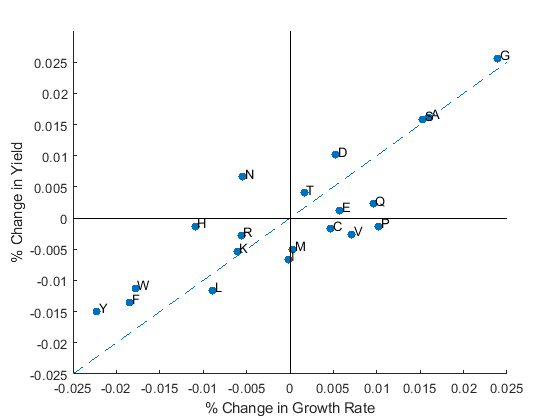



scatterlabels = {'A' 'R' 'N' 'D' 'C' 'E' 'Q' 'G' 'H' 'I' 'L' 'K' 'M' 'F' 'P' 'S' 'T' 'W' 'Y' 'V'};
d = tab(tab.foldchange == max(foldchanges),:);
fluxbars = 100*((d.max_obj_flux(1:20)/d.max_obj_flux(21))-1);
biobars = 100 * ((d.biomass_final(1:20)/d.biomass_final(21)) - 1);
scatter(fluxbars,biobars,'filled')
dx = .00025;
dy = .0007;
text(dx+fluxbars,dy+biobars,scatterlabels, 'FontSize', 10)
xlabel('% Change in Growth Rate')
ylabel('% Change in Yield')
%xlim([-1.5 1.5])
%ylim([-2 2])
r1 = refline(1,0);
r1.LineStyle = '--';
r2 = line([0 0],[-4 6]);
r2.Color = 'k';
r3 = refline(0,0);
r3.Color = 'black';

%Plot data from  the objtab table from s4_generate_variable_AA_objfluxOnly
aminos = {'ala-L[c]' 'arg-L[c]' 'asn-L[c]' 'asp-L[c]' 'cys-L[c]' 'gln-L[c]' 'glu-L[c]'...
    'gly[c]' 'his-L[c]' 'ile-L[c]' 'leu-L[c]' 'lys-L[c]' 'met-L[c]' 'phe-L[c]' 'pro-L[c]' ...
    'ser-L[c]' 'thr-L[c]' 'trp-L[c]' 'tyr-L[c]' 'val-L[c]'};
aminos = {'Ala-tRNA(Ala) [cytoplasm]' 'Arg-tRNA(Arg) [cytoplasm]' ...
    'Asn-tRNA(Asn) [cytoplasm]' 'Asp-tRNA(Asp) [cytoplasm]' 'Cys-tRNA(Cys) [cytoplasm]' 'Gln-tRNA(Gln) [cytoplasm]' ...
    'Glu-tRNA(Glu) [cytoplasm]' 'Gly-tRNA(Gly) [cytoplasm]' 'His-tRNA(His) [cytoplasm]' 'Ile-tRNA(Ile) [cytoplasm]' ...
    'Leu-tRNA(Leu) [cytoplasm]' 'Lys-tRNA(Lys) [cytoplasm]' 'Met-tRNA(Met) [cytoplasm]' 'Phe-tRNA(Phe) [cytoplasm]' ...
    'Pro-tRNA(Pro) [cytoplasm]' 'Ser-tRNA(Ser) [cytoplasm]' 'Thr-tRNA(Thr) [cytoplasm]' 'Trp-tRNA(Trp) [cytoplasm]' ...
    'Tyr-tRNA(Tyr) [cytoplasm]' 'Val-tRNA(Val) [cytoplasm]'};
colors = jet(20);
figure();
hold on;
for i = 1:20
    aa = aminos{i};
    subtab = objtab(strcmp(aminos{i},objtab.AA),:);
    foldchanges = subtab.foldchange;
    plot(subtab.foldchange, subtab.flux_ratio,'color',colors(i,:));
end
legend(aanames,'location','eastoutside');

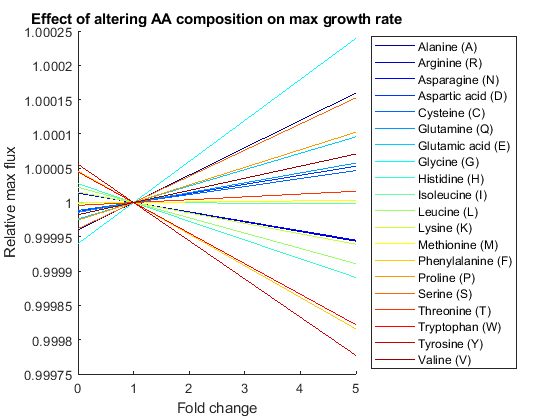

ylabel('Relative max flux');
xlabel('Fold change');
title('Effect of altering AA composition on max growth rate');
hold off;


getEnzMassPerG(objtab.model{end})

ans = 0

[~,biomassrank] = sort(tab.biomass_final(1:20),'descend');
[~,biomassrank] = sort(biomassrank); %convert the order into ranks

rows = objtab(objtab.foldchange == 1.5,:);
[~,fluxrank] = sort(rows.max_obj_flux,'descend');
[~,fluxrank] = sort(fluxrank);


%get totalcounts and abundancerank from s4.2_AA_comp...mlx
ranktab = table();
ranktab.aa = aminos';
effect = tab.max_obj_flux(1:20) > tab.max_obj_flux(21);
ranktab.increase_effect(effect) = '+';
ranktab.increase_effect(~effect) = '-';
ranktab.biomass_final = tab.biomass_final(1:20);
ranktab.max_obj_flux = rows.max_obj_flux;
ranktab.abundance = totalcounts;
ranktab.biomass_rank = biomassrank;
ranktab.flux_rank = fluxrank;
ranktab.abundance_rank = abundancerank

ranktab = 20×8 table
        aa        increase_effect    biomass_final    max_obj_flux    abundance    biomass_rank    flux_rank    abundance_rank
    __________    _______________    _____________    ____________    _________    ____________    _________    ______________
    'ala__L_c'           -             0.083321          5.6395        157.49           19             2               2      
    'arg__L_c'           +             0.083325          5.6393         49.53            8            14              16      
    'asn__L_c'           +             0.083323          5.6393        91.494           16            13               8      
    'asp__L_c'           -             0.083323          5.6394        9

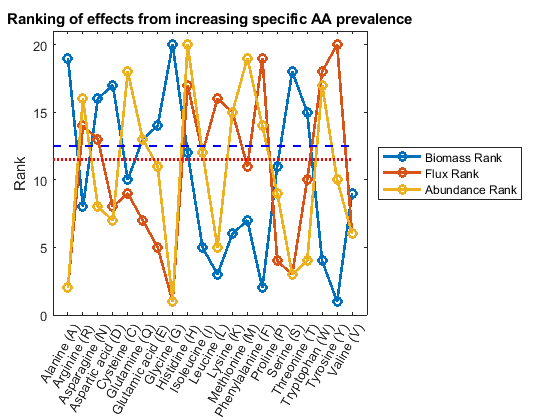


plot(1:20,ranktab.biomass_rank,'-o',1:20,ranktab.flux_rank,'-o',1:20,ranktab.abundance_rank,'-o','lineWidth',2)
%add ref lines
%biomass of the default model
defbiorank = sum(ranktab.biomass_final > tab.biomass_final(21)) + 0.5;
hline = refline(0,defbiorank);
hline.Color = 'b';
hline.LineStyle = '--';
hline.LineWidth = 2;
%flux of the default model
deffluxrank = sum(ranktab.max_obj_flux > tab.max_obj_flux(21)) + 0.5;
hline2 = refline(0,deffluxrank);
hline2.Color = 'r';
hline2.LineStyle = ':';
hline2.LineWidth = 2;

legend({'Biomass Rank' 'Flux Rank' 'Abundance Rank'},'location','eastoutside');
title('Ranking of effects from increasing specific AA prevalence')
ylabel('Rank');
set(gca,'XTick',1:20,'XTickLabel',aanames,'XTickLabelRotation',60);
xlim([0 21]);
ylim([0 21]);

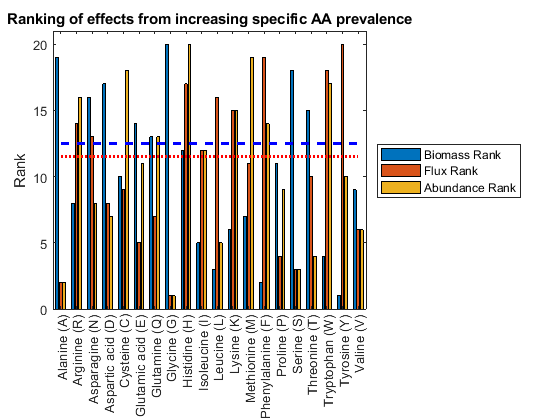


bar(categorical(aanames(1:20)),horzcat(ranktab.biomass_rank,ranktab.flux_rank,ranktab.abundance_rank));

title('Ranking of effects from increasing specific AA prevalence')
ylabel('Rank');
ylim([0,21]);
%add ref lines
%biomass of the default model
hold on;
plot(xlim,[defbiorank defbiorank],'--b','lineWidth',2);
%flux of the default model
plot(xlim,[deffluxrank deffluxrank],':r','lineWidth',2);
legend({'Biomass Rank' 'Flux Rank' 'Abundance Rank'},'location','eastoutside');
hold off;

corrcoef(biomassrank,fluxrank)

ans =     1.0000   -0.7955
   -0.7955    1.0000


corrcoef([biomassrank,fluxrank,abundancerank])

ans =     1.0000   -0.7955   -0.5383
   -0.7955    1.0000    0.5759
   -0.5383    0.5759    1.0000


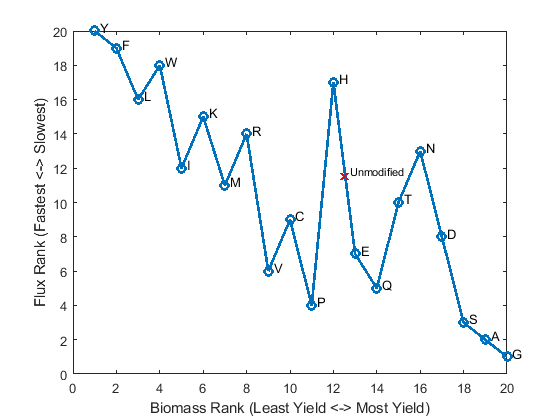

plot(biomassrank(order),fluxrank(order),'-o','linewidth',2)
xlabel('Biomass Rank (Least Yield <-> Most Yield)')
ylabel('Flux Rank (Fastest <-> Slowest)')
dx = .25;
dy = .25;
text(dx+biomassrank(order),dy+fluxrank(order),scatterlabels(order), 'FontSize', 10)
neutraly = 11.5;
neutralx = 12.5;
hold on;
plot(neutralx,neutraly,'r-x','linewidth',2);
text(dx+neutralx,dy+neutraly,'Unmodified','FontSize',8);
hold off;